clear all

data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;

A=data.A;
B=data.B;
C=data.C;
D=data.D;
sys1 = ss(A,B,C,D);
s = tf('s');
Plant = -FWT(1,3);
Kp = 0;
Ki = 0.26;
Kd = 0;
Tf=0;
K = pid(Kp, Ki, Kd);

H=1/(1+K*Plant)

H =
 
  A = 
                            ?  Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   ?                        0            -1             0             0             0             0
   Omega (rad/s       -0.0573        -0.422       -0.2204             0       -0.2204             0
   z1dot (m/s)      -0.002489       0.02328      -0.01085         -0.04     -0.009574             0
   z1 (m)                   0             0             1             0             0             0
   z2dot (m/s)       -0.01556        0.1455      -0.05984             0       -0.1651        -10.82
   z2 (m)                   0             0             0             0             1             0
 
  B = 
                       u1
   ?                    0
   Omega (rad/s    0.2204
   z1dot (m/s)   0.009574
   z1 (m)               0
   z2dot (m/s)    0.05984
   z2 (m)               0
 
  C = 
                  ?  Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (

t=0:0.1:19

t =          0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    1.1000    1.2000    1.3000    1.4000    1.5000    1.6000    1.7000    1.8000    1.9000    2.0000    2.1000    2.2000    2.3000    2.4000    2.5000    2.6000    2.7000    2.8000    2.9000    3.0000    3.1000    3.2000    3.3000    3.4000    3.5000    3.6000    3.7000    3.8000    3.9000    4.0000    4.1000    4.2000    4.3000    4.4000    4.5000    4.6000    4.7000    4.8000    4.9000


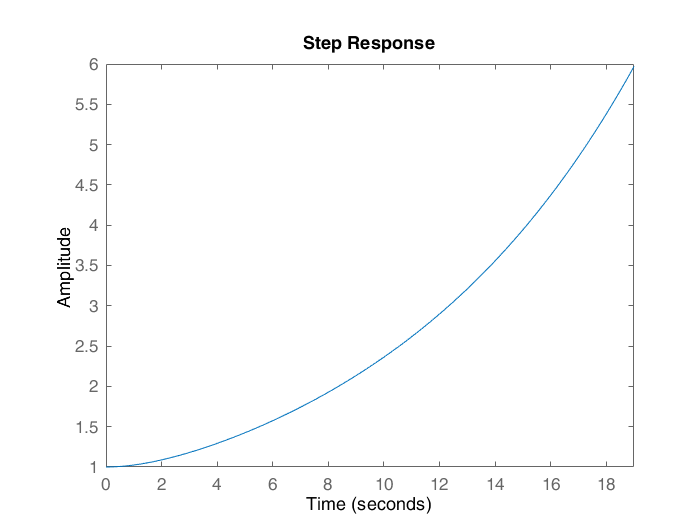

step(H,t)